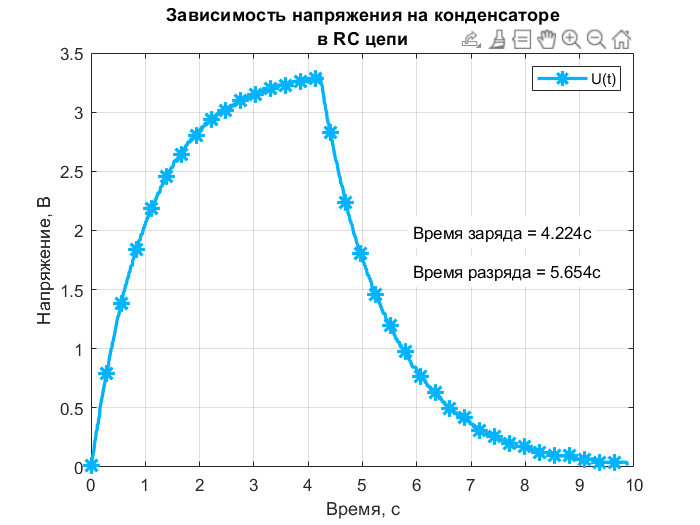

close all;
clear variables ;
 
data = importdata("data.txt");
scale = importdata("settings.txt");

dV = scale(1);
dt = scale(2);

u = data * dV;
t = ((1:length(data)) * dt)';

[M,I] = max(data,[], 'linear');
tCharge = t(I);
tDisCharge = t(end) - tCharge;

f1 = figure();
plot(t, u, 'b-*', 'MarkerIndices', 1:25:length(u), 'LineWidth', 2, 'MarkerSize', 10, 'Color',[0,0.7,1]);
set(gcf, 'visible', 'on');
grid on;
title({'Зависимость напряжения на конденсаторе' 'в RC цепи'});
xlabel("Время, с");
ylabel("Напряжение, В");
legend("U(t)", 'Location','northeast');
text(max(t) * 0.6, max(u) * 0.6, ['Время заряда = ' num2str(tCharge), 'c'], "BackgroundColor", 'w');
text(max(t) * 0.6, max(u) * 0.5, ['Время разряда = ' num2str(tDisCharge), 'c'], "BackgroundColor", 'w');

saveas(f1, "capacitor.png");
saveas(f1, "capacitor.svg");